% transformed = mesh_tr;

'mesh_tr'은(는) 인식할 수 없는 함수 또는 변수입니다.

% 
% C1 = mesh.spheres{1,16}.center; 
% C2 = mesh.spheres{1,15}.center; 
% C3 = mesh.spheres{1,14}.center; 
% C4 = mesh.spheres{1,13}.center; 
% CP1 = [C1; C2; C3; C4];
% 
% Cs1 = transformed.spheres{1,16}.center; 
% Cs2 = transformed.spheres{1,15}.center; 
% Cs3 = transformed.spheres{1,14}.center; 
% Cs4 = transformed.spheres{1,13}.center; 
% CP2 = [Cs1; Cs2; Cs3; Cs4];
% 
% figure()
% hold on
% axis equal
% axis off
% %plot3(CP1(1:3,1),CP1(1:3,2),CP1(1:3,3),'*-k')
% plot3(mesh.vertices(:,1),mesh.vertices(:,2),mesh.vertices(:,3),'.k')
% hold off
% 
% figure()
% hold on
% axis equal
% axis off
% %plot3(CP2(1:3,1),CP2(1:3,2),CP2(1:3,3),'*R')
% plot3(transformed.vertices(:,1),transformed.vertices(:,2),transformed.vertices(:,3),'.R')
% hold off

% figure()
% hold on;
% axis equal
% axis off
% scatter3(mesh.centers([16:20 22],1),mesh.centers([16:20 22],2),mesh.centers([16:20 22],3),'*r');
% h = trimesh(mesh.faces, mesh.vertices(:, 1), mesh.vertices(:, 2), mesh.vertices(:, 3), 'EdgeColor', 'none', 'FaceColor', [0.5, 0.5, 0.5], 'FaceAlpha', 0.5);
% view([-90,0]);
% camlight;
% view([90, 0]);
% camlight;
% view_angle = [207,10];
% view(view_angle);
% lighting gouraud;
% camlight;
% hold off

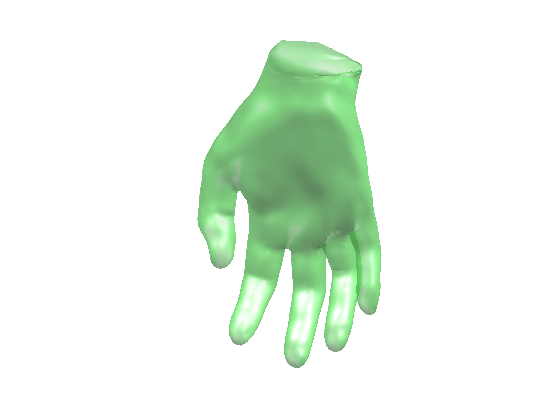

figure()
hold on;
view_angle = [207,10];
view(view_angle);
trimesh(mesh.faces, mesh.vertices(:, 1), mesh.vertices(:, 2), mesh.vertices(:, 3), 'EdgeColor', 'none', 'FaceColor', [0.4, 0.9, 0.4], 'FaceAlpha', 0.5);
%trimesh(transformed.faces, transformed.vertices(:, 1), transformed.vertices(:, 2), transformed.vertices(:, 3), 'EdgeColor', 'none', 'FaceColor', [0.4, 0.9, 0.4], 'FaceAlpha', 0.5);
%trimesh(tr_mesh.faces, tr_mesh.vertices(:, 1), tr_mesh.vertices(:, 2), tr_mesh.vertices(:, 3), 'EdgeColor', 'none', 'FaceColor', [0.4, 0.9, 0.4], 'FaceAlpha', 0.5);
%trimesh(mesh.faces, V_P1(:, 1), V_P1(:, 2), V_P1(:, 3), 'EdgeColor', 'none', 'FaceColor', [0.4, 0.9, 0.4], 'FaceAlpha', 0.5);
trimesh(points.faces, points.vertices(:, 1), points.vertices(:, 2), points.vertices(:, 3), 'EdgeColor', 'none', 'FaceColor', [0.8, 0.8, 0.8], 'FaceAlpha', 0.5);
%quiver3(vertices(:, 1), vertices(:, 2), vertices(:, 3), normals(:, 1), normals(:, 2), normals(:, 3), 'Color', [0.4, 0.9, 0.4]);
%quiver3(points.vertices(:, 1), points.vertices(:, 2), points.vertices(:, 3), points.normals(:, 1), points.normals(:, 2), points.normals(:, 3), 'Color', [0.8, 0.8, 0.8]);

view([-90,0]);
camlight;
view([90, 0]);
camlight;
view(view_angle);
axis equal;
grid off;
lighting gouraud;
axis off;
view([185, 8]);
camlight;
hold off;
